# Loading images

Uncomment images below to load images of different kinds. 

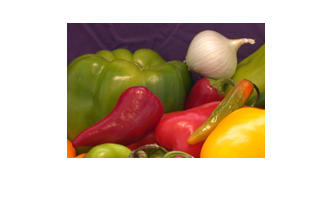

%im = imread('engineer.png'); %gray scale
%im = imread('chickens.png'); %gray scale
%im = imread('bergen.jpg'); %gray scale
%im = imread('yellowlily.jpg'); %Color image
im = imread('onion.png'); %Color image
%im = imread('twins.jpg'); %Color image
figure, imshow(im)

## Display each component of RGB Color spaces

Red


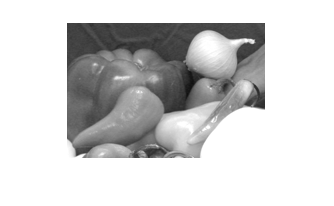

Green


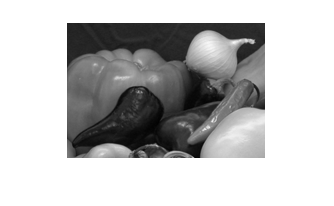

Blue


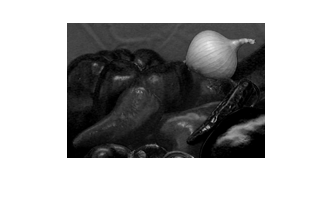

if length(size(im)) == 3
    imr = im(:,:,1);
    img = im(:,:,2);
    imb = im(:,:,3);
    disp('Red')
    figure, imshow(imr)
    disp('Green')
    figure, imshow(img)
    disp('Blue')
    figure, imshow(imb)
end

## Converting uint8 to double

Simply casting is not sufficient. Will show image incorrectly. Why? Because imshow displays values between 0-255 for uint8 and 0-1 for double

disp('imd1')

imd1


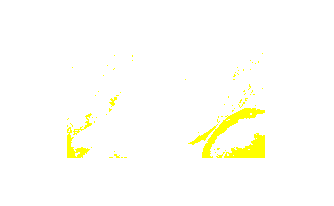

imd1 = double(im);
figure, imshow(imd1)

Use im2double to convert image correctly into the double format. What is the difference between imd2 and imd1? Check up their values in the workspace.

disp('imd2')

imd2


imd2 = im2double(im);
figure, imshow(imd2)

**TODO**: Divide image (im) by 255. Store into variable imd3 and show the image. Ensure type of imd3 is 'double'.

%COMPLETE THIS SNIPPET OF CODE.
disp('imd3')

imd3


imby255 = double(im)/255;
imd3 =  im2double(im)

imd3 = imd3(:,:,1) =

    0.2471    0.2627    0.2549    0.2667    0.2588    0.2510    0.2471    0.2588    0.2667    0.2667    0.2510    0.2392    0.2392    0.2549    0.2941    0.3176    0.3137    0.3137    0.3059    0.2824    0.2588    0.2392    0.2157    0.2196    0.2235    0.2157    0.2314    0.2588    0.2588    0.2784    0.2706    0.2627    0.2588    0.2549    0.2471    0.2510    0.2588    0.2431    0.2510    0.2588    0.2706    0.2941    0.3098    0.2980    0.2824    0.2706    0.2510    0.2510    0.2667    0.2549    0.2471    0.2549    0.2627    0.2667    0.2471    0.2667    0.2745    0.2667    0.2745    0.2627    0.2588    0.2667    0.2706    0.2549    0.2471    0.2510    0.2627    0.2627    0.2510    0.2627    0.2706    0.2745    0.2745    0.2627    0.2706    0.2706    0.2784    0.2784    0.2784    0.2667    0.2627    0.2706    0.2706    0.2667    0.2706    0.2745    0.2784    0.2667    0.2627    0.2510    0.2510    0.2471    0.2588    0.2784    0.2824    0.2706    0.2627    0.26

%---------------------------%
disp('imd3 image')

imd3 image


figure, imshow(imd3)

%---------------------------%
disp('imby255 image')

imby255 image


figure, imshow(imby255)

## Creating binary image

if -else statement below checks whether image is gray-level or color

*imshow* only works for 2D logical data. For 3D logical data, need a workaround in else statement

if length(size(im)) == 2 %gray-level image. Choose a gray-scale image in section 1 for this statement to be true 
    imbw = im > 111; %Creating a logical (0/1) matrix. Check its type in workspace. This is an example of vector operation!
    figure, imshow(imbw);
else %color - image
    imbw = im > 111;

**            TODO**: We can't display 3D logical matrix. So convert it into uint8/double. Make sure after conversion values are what imshow expects for that datatype

imbw1 = imbw1(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

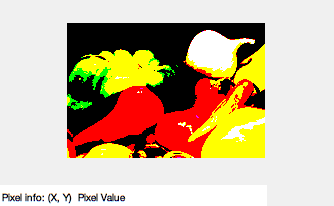

    %COMPLETE THIS SNIPPET OF CODE.
    imbw1 = double(imbw)
    figure, imshow(imbw1), impixelinfo;
end

## Averaging RGB components (the wrong way)

if length(size(im)) == 3
    imr = im(:,:,1);
    img = im(:,:,2);
    imb = im(:,:,3);
    
    %Compute average directly: NO NEED OF A FOR LOOP!! Another example of vector operation.
    imavg1 = (imr + img + imb)/3; 
    

            **TODO**: Explain to your team why the output is incorrect. uint 8 cant store pass 255

imavg1


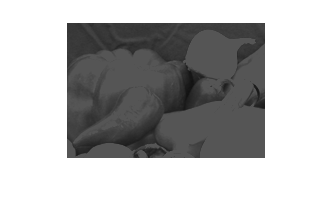

    disp('imavg1')
    figure, imshow(imavg1); 
end

## Averaging RGB components (the right way but is it equivalent to Matlab's rgb2gray?)

if length(size(im)) == 3
    
    %Getting R, G, B channels from the image im and storing them in
    %different variables
    imr = im(:,:,1);
    img = im(:,:,2);
    imb = im(:,:,3);            
    

            **TODO**: Write down the expression for averaging rgb color components correctly (Do not repeat the wrong way shown in the previous section!)

    disp('imavg')
    imavg = imr/3 + img/3 + imb/3; 
    figure, imshow(imavg), impixelinfo
    
    

            Matlab's method to compute gray level image from color using the function *rgb2gray*

    disp('imgray')
    imgray = rgb2gray(im);
    figure, imshow(imgray) 

            Question:  Are *imgray* and *imavg* storing exactly the same values? Let's find out by computing their difference and checking if it is zero or not.

            **TODO**: Compute the absolute difference between these images using vector operations. The result should have the same size as of imgray/imavg.

    %Note 1: Take absolute differece
    %Note 2: If you subtract two uint8s what can you expect to get? In
    %other words, when computing the difference, keep in mind the datatype of the images.
    %Note 3: Do not use a for-loop to find the difference. Use vector
    %operation.
    double_imgray = double(imgray)
    double_imavg = double(imavg)
    %Complete Code snippet
    diff = abs(double_imgray - double_imavg)
    

            **TODO**: Add up all the elements of the matrix diff to get a single value.

imavg


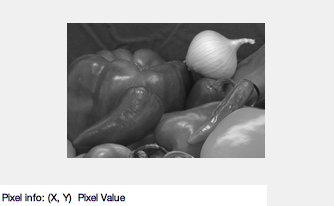

imgray


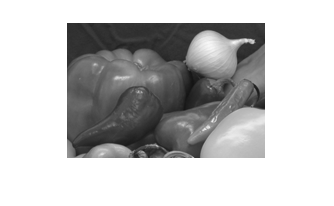

double_imgray =     47    48    46    48    49    49    48    48    48    48    45    43    46    50    54    57    59    59    57    53    49    45    41    43    44    43    42    48    49    52    51    51    51    50    48    49    49    45    48    50    52    58    59    58    55    52    49    48    48    49
    47    46    46    48    48    50    49    48    46    46    44    43    45    46    49    56    58    58    57    56    53    48    43    42    43    42    42    49    50    51    50    52    53    50    48    47    46    46    47    46    48    52    55    59    58    55    51    50    48    49
    46    46    48    47    48    48    49    49    47    46    46    43    44    43    44    51    55    58    57    54    54    51    46    39    38    40    44    49    49    50    50    52    51    49    47    46    46    44    44    42    41    42    44    51    55    53    51    50    49    49
    47    47    48    47    48    46    48    48    47    46    47    46    46   

double_imavg =     54    56    54    57    56    56    56    56    55    56    52    50    53    58    62    66    68    69    66    61    56    52    48    51    52    49    49    56    57    60    59    58    58    58    56    56    56    53    55    57    59    64    66    65    62    60    56    54    56    57
    54    53    53    56    56    57    56    56    53    52    51    50    53    53    56    63    67    67    66    63    60    55    50    49    51    48    49    59    58    58    59    59    62    57    56    54    53    53    55    53    54    60    63    67    66    62    58    57    55    57
    52    52    54    56    56    55    56    56    54    53    53    51    51    51    53    59    63    66    66    62    62    59    53    45    46    47    50    56    55    57    57    59    59    58    55    53    53    52    52    48    47    49    51    58    62    60    59    57    56    58
    55    54    54    56    56    53    55    55    54    54    54    54    53    

diff =      7     8     8     9     7     7     8     8     7     8     7     7     7     8     8     9     9    10     9     8     7     7     7     8     8     6     7     8     8     8     8     7     7     8     8     7     7     8     7     7     7     6     7     7     7     8     7     6     8     8
     7     7     7     8     8     7     7     8     7     6     7     7     8     7     7     7     9     9     9     7     7     7     7     7     8     6     7    10     8     7     9     7     9     7     8     7     7     7     8     7     6     8     8     8     8     7     7     7     7     8
     6     6     6     9     8     7     7     7     7     7     7     8     7     8     9     8     8     8     9     8     8     8     7     6     8     7     6     7     6     7     7     7     8     9     8     7     7     8     8     6     6     7     7     7     7     7     8     7     7     9
     8     7     6     9     8     7     7     7     7     8     7     8     7     6     8

diffsum = 371021

Difference between imgray and imavg is 13.880322 per pixel


    diffsum = sum(sum(diff))
    % or sum(diff(:))
    fprintf('Difference between imgray and imavg is %f per pixel\n', diffsum/(size(im,1)*size(im, 2)));
   
end

## Quantization (Process of reducing unique number of gray levels from 255 to, say, 16) 

## Toy example

%Create a 1 x 16 uint8 vector 
val = uint8(0:16:16*15); 

%Reshape it into a 4 x 4 matrix
valmat = reshape(val, 4, 4); 

%Divide by 64. Values (less than 64) map to 0. Values between (64 and 127) mapped to 1 . And so on... Why?: Because the datatype of val is uint8 and so the output of division is also uint8 
%Check the range of zmat_pre in workspace. Vector val has been quantized to gray levels 0 through 4
zmat_pre = valmat/64;  

**TODO**: Check and compare val and zmat_post in the workspace. Vector val has been quantized to specific gray values 0, 64, 128, 192, and 255

%Multiply by 64 again for display.
zmat_post = zmat_pre*64;

## Quantization on an image: Method 1

%Method 1: requires a gray-scale image since it produces an indexed image.
%Choose a grayscale image in the first section above
im = imread('onion.png')

im = 135×198×3 uint8 array
im(:,:,1) =

    63    67    65    68    66    64    63    66    68    68    64    61    61    65    75    81    80    80    78    72    66    61    55    56    57    55    59    66    66    71    69    67    66    65    63    64    66    62    64    66    69    75    79    76    72    69    64    64    68    65    63    65    67    68    63    68    70    68    70    67    66    68    69    65    63    64    67    67    64    67    69    70    70    67    69    69    71    71    71    68    67    69    69    68    69    70    71    68    67    64    64    63    66    71    72    69    67    67    67    70    71    75    70    65    71    75    72    73    76    78    78    80    83    86    84    77    73    69    71    69    68    68    71    69    69    74    74    72    71    72    74    75    78    75    68    73    74    72    71    70    72    70    73    75    76    73    71    70    73    74    73    68    67    67    67    68    70    71    70    75

L = 8; %Number of levels to which the image needs to be quantized
imq1 = grayslice(im, L); %Produces an image with values between 0 and L. This acts as an indexed image

Directly showing the image imq1 will make it look very dark (since L << 255). Try it on Command window!: figure, imshow(imq1);

The values need to be spread to the entire range by interpreting these values as an index to a colormap: figure, imshow(imq1, gray(L)); where gray is a Matlab function. 

**TODO 1**: Change the value of L and examine the difference in output

**TODO 2**: Change the colormap and examine the difference in output

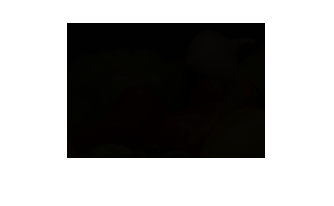

figure, imshow(imq1, gray(L)); %Can use different colormaps like summer(L), pink(L), jet(L) etc. Try it!

figure, imshow(imq1, gray(2));

figure, imshow(imq1, gray(3));

figure, imshow(imq1, jet(4));

figure, imshow(imq1, pink(5));

figure, imshow(imq1, summer(10));

## Quantization on an image: Method 2

Method 2: Just like the toy example, divide the image by a constant so that you get values between 0 and L. Then use a colormap to visualize it.

**TODO**: Initialize a constant v with which you will divide the entire image 

%Hint: It is not equal to L (because we want the values to be between 0 and L after dividing). 
%What we essentially want is for the largest gray value in original image (255) to map to L 
v = 31.875 %256/L

v = 31.8750

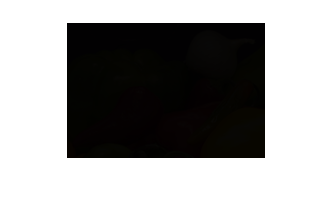

imq = (im/v);
%Directly showing this image will make it look very dark (since L << 255). 
%The values need to be spread to the entire range by interpreting these values as an index to a colormap
figure, imshow(imq, gray(L));

## Spatial resolution: Represents the density of pixels over the image

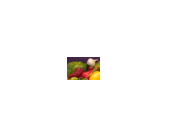

k = 6;
imdown = imresize(im, 1/k); %Re-size the image - make it k times smaller
figure, imshow(imdown)


imup = imresize(imdown, k, 'nearest'); %To visualize what information has been lost, resize it back to original size

**TODO**: Change the value of k and observe the difference in output

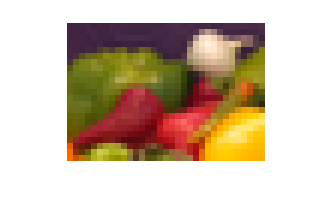

figure, imshow(imup)